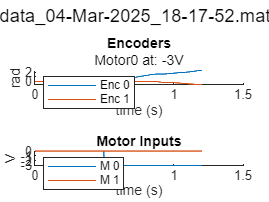

filelist = ["data_04-Mar-2025_10.mat","data_04-Mar-2025_14-46-39.mat","data_04-Mar-2025_14-48-35.mat","data_04-Mar-2025_14-49-36.mat","data_04-Mar-2025_15-02-19.mat","data_04-Mar-2025_15-04-28.mat","data_04-Mar-2025_15-06-09.mat","data_04-Mar-2025_15-07-04.mat","data_04-Mar-2025_15-13-13.mat","data_04-Mar-2025_15-16-08.mat","data_04-Mar-2025_15-27-48.mat","data_04-Mar-2025_15-29-27.mat","data_04-Mar-2025_15-30-56.mat","data_04-Mar-2025_15-31-20.mat","data_04-Mar-2025_15-33-26.mat","data_04-Mar-2025_15-34-00.mat","data_04-Mar-2025_15-37-14.mat","data_04-Mar-2025_15-39-43.mat","data_04-Mar-2025_15-42-28.mat","data_04-Mar-2025_15-43-46.mat","data_04-Mar-2025_15-47-42.mat","data_04-Mar-2025_15-49-10.mat","data_04-Mar-2025_15-51-30.mat","data_04-Mar-2025_15-52-22.mat","data_04-Mar-2025_15-54-09.mat","data_04-Mar-2025_15-57-04.mat","data_04-Mar-2025_16-08-14.mat","data_04-Mar-2025_16-11-22.mat","data_04-Mar-2025_16-14-18.mat","data_04-Mar-2025_16-16-56.mat","data_04-Mar-2025_16-18-18.mat","data_04-Mar-2025_16-21-30.mat","data_04-Mar-2025_16-24-24.mat","data_04-Mar-2025_16-29-52.mat","data_04-Mar-2025_16-55-40.mat","data_04-Mar-2025_17-24-37.mat","data_04-Mar-2025_17-40-31.mat","data_04-Mar-2025_17-41-21.mat","data_04-Mar-2025_17-43-22.mat","data_04-Mar-2025_17-50-09.mat","data_04-Mar-2025_17-51-54.mat","data_04-Mar-2025_17-54-59.mat","data_04-Mar-2025_17-57-30.mat","data_04-Mar-2025_17-57-53.mat","data_04-Mar-2025_18-00-51.mat","data_04-Mar-2025_18-01-13.mat","data_04-Mar-2025_18-03-09.mat","data_04-Mar-2025_18-06-22.mat","data_04-Mar-2025_18-07-09.mat","data_04-Mar-2025_18-09-15.mat","data_04-Mar-2025_18-10-36.mat","data_04-Mar-2025_18-11-39.mat","data_04-Mar-2025_18-12-13.mat","data_04-Mar-2025_18-13-24.mat","data_04-Mar-2025_18-14-40.mat","data_04-Mar-2025_18-15-39.mat","data_04-Mar-2025_18-16-46.mat","data_04-Mar-2025_18-17-52.mat","data_04-Mar-2025_18-18-49.mat"];

n_exp = 58;
% n_exp = find(filelist == "data_04-Mar-2025_17-41-21.mat" )
load("lab1/data/"+filelist(n_exp),"data");
%plot(data(1,:),data(2,:))
smartPlotEncVoltage(data,filelist(n_exp),false);


Ts = 0.002; % get sampling period
t = data(1,:);
x = data(2,:);
% fs = 1/Ts
% fnyq = fs/2
% fpb = 40                   % 40 Hz bassband
% b = fir1(1, fpb/fnyq, 'low'); % low freq filter
% y = filter(b,1,x);
% 
% figure
% plot(t,x,t,y)


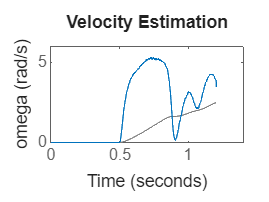

pole1 = 40*3;
pole2 = 200*5;
derivAndLowPass = zpk([0],[-pole1 -pole2],(pole1 *pole2));

% bode(derivAndLowPass)
figure;
lsimplot(derivAndLowPass,x(1:end)*pi/2048,t(1:end));
title("Velocity Estimation");
ylabel("omega (rad/s)");


[y,~] = lsim(derivAndLowPass,x(1:end)*pi/2048,t(1:end));

% Curve Fitting on speed
t05id = find(t == 0.5 )

t05id = 251

t_endTrans =  find(t == 0.80 )

t_endTrans = 401

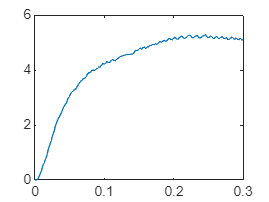


t_focus = t(t05id:t_endTrans)-0.5;
y_focus = y(t05id:t_endTrans)';
plot(t_focus,y_focus)

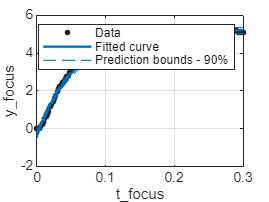


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( t_focus, y_focus );

% Set up fittype and options.
ft = fittype( 'a*(1-exp(b*(x-d)))', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.469390641058206 0.0119020695012414 0.162182308193243];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData, 'predobs', 0.9 );
% legend( h, 'y_focus vs. t_focus', 'untitled fit 1', 'Lower bounds (untitled fit 1)', 'Upper bounds (untitled fit 1)', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 't_focus', 'Interpreter', 'none' );
ylabel( 'y_focus', 'Interpreter', 'none' );
grid on


fitresult.b

ans = -17.5620

tau = 1/fitresult.b

tau = -0.0569

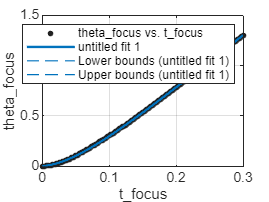

%% Curve fitting on angle
theta_focus = x(t05id:t_endTrans)*pi/2048;
% plot(t_focus,theta_focus)

%% Fit: 'untitled fit 1'.
[xDataTheta, yData] = prepareCurveData( t_focus, theta_focus );

% Set up fittype and options.
ft = fittype( 'a*(x-d)+a*tau*(exp(-(x-d)/tau)-1)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [-10 -0.1 0];
opts.StartPoint = [0.942050590775485 0.353158571222071 0.234779913372406];
opts.Upper = [10 0.1 0.1];

% Fit model to data.
[fitresultTheta, gofTheta] = fit( xDataTheta, yData, ft, opts );

% Create a figure for the plots.
figure( 'Name', 'untitled fit 1' );

% Plot fit with data.
h = plot( fitresultTheta, xDataTheta, yData, 'predobs', 0.9 );
legend( h, 'theta_focus vs. t_focus', 'untitled fit 1', 'Lower bounds (untitled fit 1)', 'Upper bounds (untitled fit 1)', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 't_focus', 'Interpreter', 'none' );
ylabel( 'theta_focus', 'Interpreter', 'none' );
grid on


fitresult.tau

ans = 0.0572

1/fitresult.tau

ans = 17.4793

## Calculations

% omega_l = 1.57;
% omega_m = 70*omega_l;
% V = 1;
% R = 2.6;
% k = 7.68e-3;
% E = k * omega_m
% I = (V-E)/R
% torque = I * k
% beta = torque/omega_m

